# Sensing System - revD

Changes since previous version:

- removed SIMULINK model integration as it was very finicky

To-Do's:

- significantly simplify the first step of loading samples into the sensing subsystem itself to be more in line with what will happen on the USRP

- Modify the simulator to be able to run off of a JSON configuration instead of having a function for each piece

## Key parts of the Sensing Subystem

### Debugging Capability

For each debuger array, the format will be as follows:

- 1st column - number of frames computed at that point

- 2nd column - number of chirps computed at that point

- remainder of columns - data taken

## Generate a Spectogram

Steps to generate spectoram:

- reshape into 1us wide windows to sample frequency at (ex: 50 samples per 1us when sampling at 50 Msps)

- reduce the number of samples in the window to the desired size of fft (ex: 32 bits)

- window the sample signal

- perform fft

### Revised Linear Model Computation:

link to resourse used to compute linear model: [https://online.stat.psu.edu/stat462/node/132/](https://online.stat.psu.edu/stat462/node/132/) 

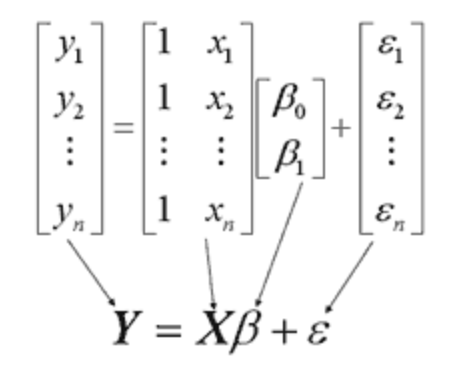

solving for this with out the Epsilon term though


$$\beta = (X^{T}X)^{-1}X^{T}Y$$


## Additional parameter settings for slope and duration

clear;
use_custom_settings = false; %uses the settings below instead of the settings in the config file
slope_MHz_us = 45;
chirp_cycle_period_us = 55;

## Initialize the simulator

simulator = Simulator_revB();
config_folder_path = "./config_files/";
config_name = "20MHz_USRP_revB.json";
% config_name = "20MHz_USRP_300us.json"; %example of a USRP configuration
% config_name = "20MHz.json";
% config_name = "100MHz.json";
% config_name = "1GHz.json";
% config_name = "4GHz.json";
simulator.load_params_from_JSON(config_folder_path + config_name);

if use_custom_settings
    %set new parameters for victim
    simulator.Victim.FrequencySlope_MHz_us = slope_MHz_us;
    simulator.Victim.ChirpCycleTime_us = chirp_cycle_period_us;
    simulator.Victim.compute_calculated_vals();

    %set attacker parameters
    simulator.Attacker.Subsystem_tracking.FrequencySlope_MHz_us = slope_MHz_us;
    simulator.Attacker.Subsystem_tracking.ChirpCycleTime_us = chirp_cycle_period_us;
    simulator.Attacker.Subsystem_tracking.compute_calculated_vals();
end

%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_realistic_attacker_and_victim_position_and_velocity();

%print out key parameters
simulator.Victim.print_radar_parameters;

Chirp Parameters
	 Start Frequency: 		 3.00 GHz
	 Frequency Slope: 		 0.10 MHz/us
	 Idle Time: 			 11.28 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 7.52 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 0.27 MSps
	 Ramp End Time: 		 248.12 us
	 Chirp Tx Bandwidth: 		 24.99 MHz
	 Chirp Sampling Bandwidth: 	 24.23 MHz
	 ADC Sampling Period: 		 240.60 us
	 Chirp Cycle Time: 		 259.40 us
	 Chirp Wavelength: 		 99.93 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 100.13 ms
	 Active Frame Time 		 66.41 ms
Performance Specifications
	 Max Range 			 395.95 m
	 Range Resolution 		 6.19 m
	 Max Velocity 			 96.31 m/s
	 Velocity Resolution 		 0.75 m/s
FMCW Specifications
	 FMCW sampling rate 		 25.00 MHz
	 Downsampling factor 		 94
	 Sweep time 			 248.12 us
	 Samples per chirp 		 6486.00 
CFAR Detection Region
	 Range Detection Region 		 24.747 m to 365.019 m
	 Velocity Detection Region 		 -91.043 m/s to 91.796 m/s


## Initialize the Target

target_range = 76;
target_velocity = 15;
simulator.load_target_realistic(target_range,target_velocity);

## Initialize the Victim and Simulation Parameters

%specify the number of frames and chirps to compute
frames_to_compute = 7;

%pre-compute the victim's chirps
simulator.Victim.precompute_radar_chirps();

%specify whether or not to record a move of the range-doppler plot
record_movie = true;
range_lims = [target_range - 1,target_range + 1.5];
vel_lims = [-1*target_velocity - 7,-1 * target_velocity + 7];
vel_exclusion_region = [-0.1,0.1];
frame_period_ms = simulator.Victim.FramePeriodicity_ms;

%whether or not the color bar should be displayed on the plots
enable_simplified_plots = false;

simulator.Victim.Radar_Signal_Processor.configure_movie_capture(frames_to_compute, ...
    record_movie,range_lims,vel_lims,vel_exclusion_region,enable_simplified_plots);

## Initialize the Attacker

%initialize the attacker parameters
simulator.Attacker.initialize_attacker(...
                        simulator.Victim.FMCW_sampling_rate_Hz * 1e-6,...
                        simulator.Victim.StartFrequency_GHz,...
                        simulator.Victim.Chirp_Tx_Bandwidth_MHz);

%initialize the sensing subsystem's debugger
simulator.Attacker.Subsystem_spectrum_sensing.initialize_debugger(1,simulator.Victim,frames_to_compute);
%set to change 1 to zero to disable

attack_type = "FN"; % or "FP"
if attack_type == "FN"
    attack_config = "range spoof - similar slope, velocity spoof - similar velocity";
elseif attack_type == "FP"
    attack_config = "target";
end

simulator.Attacker.Subsystem_attacking.set_attack_mode(attack_config);


%if it is desired to specify a specific attack location
if attack_type == "FP"
    desired_pos = 76;
    desired_vel = -5;
    simulator.Attacker.Subsystem_attacking.set_desired_attack_location(desired_pos,desired_vel);
end

## Rewritten Attacker Code

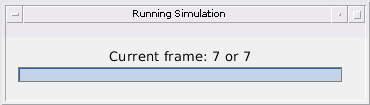

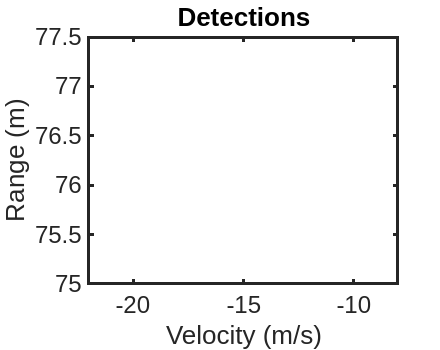

simulator.run_simulation_with_attack(frames_to_compute,true);

% %print out the relevant information
fprintf("Average Frame Duration: %5.3f us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_frame_duration);

Average Frame Duration: 100127.820 us

fprintf("Average Chirp Duration: %3.3f us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_chirp_duration);

Average Chirp Duration: 259.416 us

fprintf("Average Slope: %1.3f MHz/us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_slope);

Average Slope: 0.101 MHz/us

%compare the predicted frame start times with the actual frame start times
actual_frame_start_times = (3:frames_to_compute).' * simulator.Victim.FramePeriodicity_ms * 1e3 ... 
                                + simulator.Victim.IdleTime_us;
predicted_frame_start_times = simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.captured_frames(2:...
    simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.num_captured_frames,7);
predicted_start_time_errors = simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.captured_frames(2:...
    simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.num_captured_frames,7) ...
                                - actual_frame_start_times;


errors_in_range = predicted_start_time_errors * 1e-6 * physconst("LightSpeed");

clf;
plot(predicted_start_time_errors);
title("Timing Estimation error vs Number of Frames")
xlabel("Number of Frames Sensed")
ylabel("error (us)")
y_lim = max(abs(predicted_start_time_errors))

y_lim = 0.4520

ylim([-y_lim, y_lim])

%add in the axis for range error
yyaxis right
plot(errors_in_range)
ylabel("corresponding range error (m)")
set(gca,"YColor", 'black')
y_lim = max(abs(errors_in_range))

y_lim = 135.5108

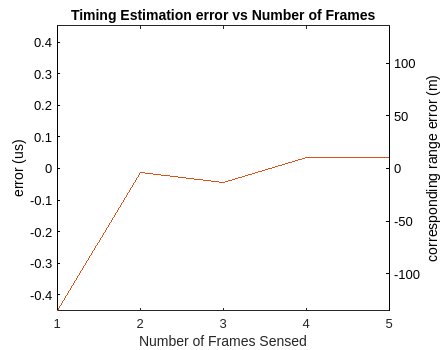

ylim([-y_lim, y_lim])

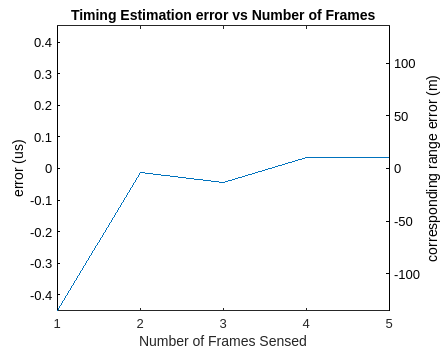

cla
print('-r300',"generated_plots/estimation_error_over_frames",'-dsvg')
print('-r300',"generated_plots/estimation_error_over_frames",'-dpng')

## Run the Debugger if enabled

if simulator.Attacker.Subsystem_spectrum_sensing.Debugger.enabled
    simulator.Attacker.Subsystem_spectrum_sensing.debugger_compute_errors(simulator.Victim);
    [summary_table] = simulator.Attacker.Subsystem_spectrum_sensing.debugger_summarize_errors();
    summary_table
end

summary_table = 4×3 table
                                  Mean        Variance        MSE    
                               __________    __________    __________

    Detected Times (us)          0.045203       0.14566        0.1475
    Detected Frequencies        -0.004552      0.001477     0.0014957
    Computed Slope             1.0592e-05    3.0942e-08    3.0409e-08
    Computed Intercept (us)      0.031234       0.02313      0.023623


### Plot Spectrogram and Generated Chirps

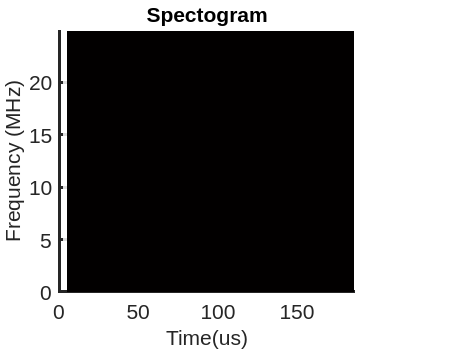

%plot spectrogram
clf;
simulator.Attacker.Subsystem_spectrum_sensing.plot_received_spectogram(200); %previously was 45
print('-r300',"generated_plots/generated_spectrogram",'-dsvg')
print('-r300',"generated_plots/generated_spectrogram",'-dpng')

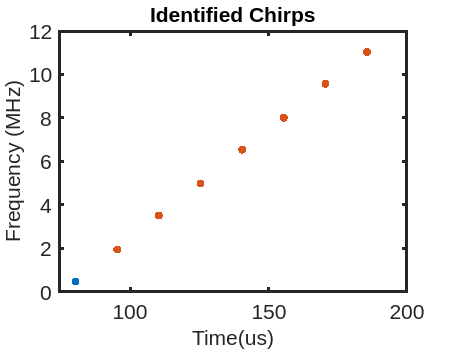

simulator.Attacker.Subsystem_spectrum_sensing.plot_clusters(200);
print('-r300',"generated_plots/identified_chirps",'-dsvg')
print('-r300',"generated_plots/identified_chirps",'-dpng')